% Heat Diffusion Simulation using Simple Implicit scheme
clear, clc

% set parameters
    l = 0.0254;         % Panel thickness (m), 1" = 0.0254m
    ipts = 11;         % Number of grid points, 101 or 201
    tsteps = 1376.9;    % Number of time steps
    k = 0.048;          % W/m-k
    rho = 140;          % kg/m^3
    c = 628;            % J/kg-K
    dx = l /(ipts-1);   % spacing in x
    alpha = k/(rho*c);  % Thermal diffusivity constant
    r = 5;              % Diffusion number, 10 times allowable time step
    ao = 2000;          % Dirichlet boundary on re-entry side

% Calculate time step, in seconds
dt = (r*(dx^2))/(alpha);

% Initialize temperature
u = 300 * ones(ipts,1);
u(1) = ao;

% Set grid locations
for i=1:ipts
    x(i) = single(i-1)*dx;
end

% Plot solution and pause
%plot(x,u);
%xlim([0, 0.0254]);
%ylim([1, 2000]);
%xlabel('Position (meters)');
%ylabel('Temperature (K)');
%title('Temperature Distribution');
%pause(3)

% Set up A matrix of coefficients

b = -r;
d = 1 + 2*r;
a = -r;
fprintf('a = %.3f, b=%.3f,d=%.3f',a,b,d)

a = -5.000, b=-5.000,d=11.000

Now we create our diagonal matricies individually to replicate

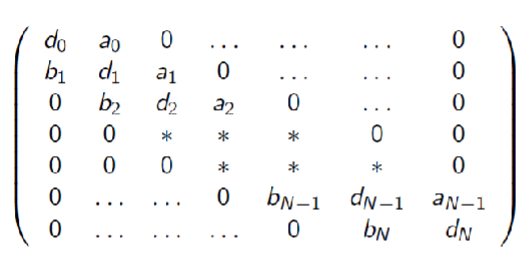

fprintf('aN matrix:\n')

aN matrix:


disp(a*diag(ones((ipts-1),1),1))

     0    -5     0     0     0     0     0     0     0     0     0
     0     0    -5     0     0     0     0     0     0     0     0
     0     0     0    -5     0     0     0     0     0     0     0
     0     0     0     0    -5     0     0     0     0     0     0
     0     0     0     0     0    -5     0     0     0     0     0
     0     0     0     0     0     0    -5     0     0     0     0
     0     0     0     0     0     0     0    -5     0     0     0
     0     0     0     0     0     0     0     0    -5     0     0
     0     0     0     0     0     0     0     0     0    -5     0
     0     0     0     0     0     0     0     0     0     0    -5
     0     0     0     0     0     0     0     0     0     0     0



fprintf('______________________')

______________________

fprintf('bN matrix:\n')

bN matrix:


disp(d*diag(ones((ipts),1),0))

    11     0     0     0     0     0     0     0     0     0     0
     0    11     0     0     0     0     0     0     0     0     0
     0     0    11     0     0     0     0     0     0     0     0
     0     0     0    11     0     0     0     0     0     0     0
     0     0     0     0    11     0     0     0     0     0     0
     0     0     0     0     0    11     0     0     0     0     0
     0     0     0     0     0     0    11     0     0     0     0
     0     0     0     0     0     0     0    11     0     0     0
     0     0     0     0     0     0     0     0    11     0     0
     0     0     0     0     0     0     0     0     0    11     0
     0     0     0     0     0     0     0     0     0     0    11



fprintf('______________________')

______________________

fprintf('dN matrix:\n')

dN matrix:


disp(b*diag(ones((ipts-1),1),-1))

     0     0     0     0     0     0     0     0     0     0     0
    -5     0     0     0     0     0     0     0     0     0     0
     0    -5     0     0     0     0     0     0     0     0     0
     0     0    -5     0     0     0     0     0     0     0     0
     0     0     0    -5     0     0     0     0     0     0     0
     0     0     0     0    -5     0     0     0     0     0     0
     0     0     0     0     0    -5     0     0     0     0     0
     0     0     0     0     0     0    -5     0     0     0     0
     0     0     0     0     0     0     0    -5     0     0     0
     0     0     0     0     0     0     0     0    -5     0     0
     0     0     0     0     0     0     0     0     0    -5     0



fprintf('______________________')

______________________

fprintf('Full A matrix:')

Full A matrix:

fprintf('A=aN+bN+dN')

A=aN+bN+dN

A = a*diag(ones((ipts-1),1),1) + d*diag(ones((ipts),1)) + b*diag(ones((ipts-1),1),-1);
disp(A)

    11    -5     0     0     0     0     0     0     0     0     0
    -5    11    -5     0     0     0     0     0     0     0     0
     0    -5    11    -5     0     0     0     0     0     0     0
     0     0    -5    11    -5     0     0     0     0     0     0
     0     0     0    -5    11    -5     0     0     0     0     0
     0     0     0     0    -5    11    -5     0     0     0     0
     0     0     0     0     0    -5    11    -5     0     0     0
     0     0     0     0     0     0    -5    11    -5     0     0
     0     0     0     0     0     0     0    -5    11    -5     0
     0     0     0     0     0     0     0     0    -5    11    -5
     0     0     0     0     0     0     0     0     0    -5    11




% Set up boundary condition coefficients for reentry side, Dirichlet

A(1,2) = 0;
A(1,1) = 1;
fprintf('______________________')

______________________

fprintf('Boundary Condition Coefficients A')

Boundary Condition Coefficients A

disp(A)

     1     0     0     0     0     0     0     0     0     0     0
    -5    11    -5     0     0     0     0     0     0     0     0
     0    -5    11    -5     0     0     0     0     0     0     0
     0     0    -5    11    -5     0     0     0     0     0     0
     0     0     0    -5    11    -5     0     0     0     0     0
     0     0     0     0    -5    11    -5     0     0     0     0
     0     0     0     0     0    -5    11    -5     0     0     0
     0     0     0     0     0     0    -5    11    -5     0     0
     0     0     0     0     0     0     0    -5    11    -5     0
     0     0     0     0     0     0     0     0    -5    11    -5
     0     0     0     0     0     0     0     0     0    -5    11




% Neumann boundary on internal side

fprintf('______________________')

______________________

fprintf('Set up Nuemann boundary conditions')

Set up Nuemann boundary conditions

A(ipts,ipts-1) = A(ipts-1, ipts-1) + 4*b;
A(ipts, ipts) = A(ipts-1, ipts)-3*b;
disp(A)

     1     0     0     0     0     0     0     0     0     0     0
    -5    11    -5     0     0     0     0     0     0     0     0
     0    -5    11    -5     0     0     0     0     0     0     0
     0     0    -5    11    -5     0     0     0     0     0     0
     0     0     0    -5    11    -5     0     0     0     0     0
     0     0     0     0    -5    11    -5     0     0     0     0
     0     0     0     0     0    -5    11    -5     0     0     0
     0     0     0     0     0     0    -5    11    -5     0     0
     0     0     0     0     0     0     0    -5    11    -5     0
     0     0     0     0     0     0     0     0    -5    11    -5
     0     0     0     0     0     0     0     0     0    -9    10




% Solve for the temperature vector

The base math equation is:

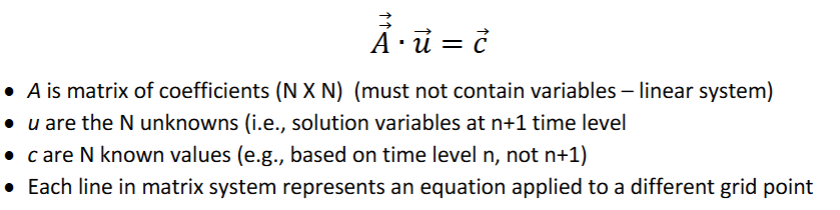

In matrix math solving for u would be done by:

But taking the inverse in unreliable, thus you can do the numerical equivalent and note that this is not division it is a special matlab opperator ('\') not ('/') which is called a 'matrix left division':

u = A\u;
% Set initial time at zero
t = 0;

% Start loop to calculate for given number of time steps
for j = 1:tsteps
    %this solves for the new time
    u = A\u;

    %this reapplies your boundary condition
    u(1) = ao;

    %The matrix multiplication doesn't actually
    %use time step as seen below, instead it is baked into 
    %the diffusivity constant and the diffusion number
    %I could set dt=0 and this code would still run
    t = t + dt;


    % Plot the temperature disbribution at each time level
    %plot(x,u);
    %xlim([0, 0.0254])
    %ylim([0,2000])
    %xlabel('Position (meters)');
    %ylabel('Temperature (K)');
    %title('Temperature Distribution');
    error('End of Example')

    %pause(0.01)

end

End of example